t = linspace(0,1)

t =          0    0.0101    0.0202    0.0303    0.0404    0.0505    0.0606    0.0707    0.0808    0.0909    0.1010    0.1111    0.1212    0.1313    0.1414    0.1515    0.1616    0.1717    0.1818    0.1919    0.2020    0.2121    0.2222    0.2323    0.2424    0.2525    0.2626    0.2727    0.2828    0.2929    0.3030    0.3131    0.3232    0.3333    0.3434    0.3535    0.3636    0.3737    0.3838    0.3939    0.4040    0.4141    0.4242    0.4343    0.4444    0.4545    0.4646    0.4747    0.4848    0.4949


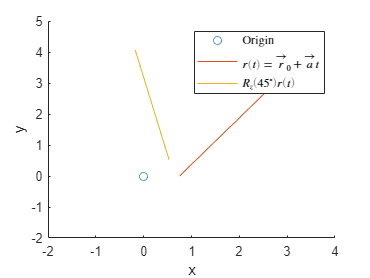

x = 2*t+3/4;
y=3*t;

r_old = [x;y];
clf
scatter(0,0)
hold on
plot(x,y)

xlim([-2,4])
ylim([-2,5])

hold on

r_new = rotz(45)*[r_old;zeros(length(r_old),1)'];
plot(r_new(1,:),r_new(2,:))
% title("$  2y+3x=4$",'interpreter','latex')
legend(["Origin","$r(t)=\vec{r}_0+\vec{a}t$","$R_z(45^\circ)r(t)$"],'interpreter','latex')
xlabel('x');
ylabel('y');

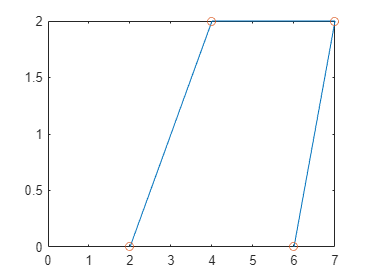

Points = [2 4 7 6;0 2 2 0];
polyline = [];
for i=1:(length(Points)-1)
    for t=linspace(0,1)
        w = (t)/(1);
        polyline = [polyline Points(:,i)*(1-w)+Points(:,i+1)*w];
    end
end
clf
plot(polyline(1,:),polyline(2,:))
xlim([0,7])
hold on
scatter(Points(1,:),Points(2,:))

syms x y
l1 = y+0.5*x-2.5

$$l1 = \frac{x}{2}+y-\frac{5}{2}$$

l2 = y-1.375*x+4.625

$$l2 = y-\frac{11\,x}{8}+\frac{37}{8}$$

l3 = y+3.5*x-8.5

$$l3 = \frac{7\,x}{2}+y-\frac{17}{2}$$

pp1 = solve([l1==0, l2==0],[x y]);
pp2 = solve([l1==0, l3==0],[x y]);
pp0 = solve([l2==0, l3==0],[x y]);
P1 = [double(pp1.x); double(pp1.y)];
P0 = [double(pp0.x); double(pp0.y)];
P2= [double(pp2.x); double(pp2.y)];

% subs
lam = 1/3

lam = 0.3333


eq = (1-lam)*l1.*l2 + lam*l3.^2;
eq =expand(eq)

$$eq = \frac{29\,x^{2}}{8}+\frac{7\,x\,y}{4}-16\,x+y^{2}-\frac{17\,y}{4}+\frac{131}{8}$$

clf

fimplicit(eq,'--')
xlim([-1,5])
ylim([-4,4])
hold on
fimplicit(l1)
hold on
fimplicit(l2)
hold on
fimplicit(l3)

hold on
allPoints = [P0,P2,P1]

allPoints =     2.6923    2.0000    3.8000
   -0.9231    1.5000    0.6000


scatter(allPoints(1,:),allPoints(2,:))

tt = linspace(0,1);
w = 0.33;
% w = sqrt((lam-1)/(4*lam))
bez = zeros(length(tt),2);
for i=1:length(tt)
    t = tt(i);
    rx = ((1-t)^2*P0(1)+2*t*(1-t)*w*P1(1) + t.^2.*P2(1))/((1-t).^2 + 2*t*(1-t)*w+t^2);
    ry = ((1-t)^2*P0(2)+2*t*(1-t)*w*P1(2) + t.^2.*P2(2))/((1-t).^2 + 2*t*(1-t)*w+t^2);
    bez(i,:) = [rx;ry];
end
bez = bez'

bez =     2.6923    2.6996    2.7069    2.7140    2.7210    2.7279    2.7346    2.7412    2.7476    2.7538    2.7598    2.7657    2.7713    2.7767    2.7818    2.7867    2.7912    2.7956    2.7996    2.8032    2.8066    2.8096    2.8123    2.8145    2.8164    2.8179    2.8190    2.8197    2.8199    2.8197    2.8190    2.8178    2.8162    2.8141    2.8115    2.8084    2.8048    2.8007    2.7961    2.7910    2.7853    2.7792    2.7725    2.7654    2.7577    2.7495    2.7409    2.7318    2.7222    2.7121
   -0.9231   -0.9126   -0.9016   -0.8900   -0.8778   -0.8650   -0.8515   -0.8374   -0.8226   -0.8071   -0.7910   -0.7742   -0.7566   -0.7384   -0.7194   -0.6997   -0.6793   -0.6582   -0.6363   -0.6136   -0.5902   -0.5661   -0.5412   -0.5156   -0.4893   -0.4623   -0.4345   -0.4060   -0.3769   -0.3471   -0.3166   -0.2855   -0.2538   -0.2216   -0.1887   -0.1554   -0.1215   -0.0872   -0.0524   -0.0172    0.0183    0.0541    0.0902    0.1266    0.1632    0.1999    0.2367    0.2736    0.3105   

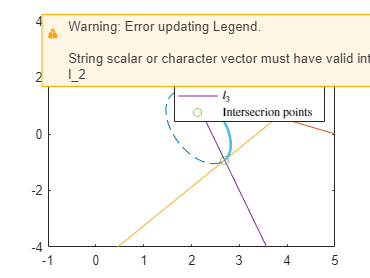

hold on
plot(bez(1,:),bez(2,:),"LineWidth",2)
legend(["$(1-\lambda) l_1 l_2 + \lambda l_3^2=0$","$l_1$","$l_2$","$l_3$","Intersecrion points"],"Interpreter","latex")

vv = linspace(0,1);
uu = linspace(0,1);
cc = bez

cc =     2.6923    2.6996    2.7069    2.7140    2.7210    2.7279    2.7346    2.7412    2.7476    2.7538    2.7598    2.7657    2.7713    2.7767    2.7818    2.7867    2.7912    2.7956    2.7996    2.8032    2.8066    2.8096    2.8123    2.8145    2.8164    2.8179    2.8190    2.8197    2.8199    2.8197    2.8190    2.8178    2.8162    2.8141    2.8115    2.8084    2.8048    2.8007    2.7961    2.7910    2.7853    2.7792    2.7725    2.7654    2.7577    2.7495    2.7409    2.7318    2.7222    2.7121
   -0.9231   -0.9126   -0.9016   -0.8900   -0.8778   -0.8650   -0.8515   -0.8374   -0.8226   -0.8071   -0.7910   -0.7742   -0.7566   -0.7384   -0.7194   -0.6997   -0.6793   -0.6582   -0.6363   -0.6136   -0.5902   -0.5661   -0.5412   -0.5156   -0.4893   -0.4623   -0.4345   -0.4060   -0.3769   -0.3471   -0.3166   -0.2855   -0.2538   -0.2216   -0.1887   -0.1554   -0.1215   -0.0872   -0.0524   -0.0172    0.0183    0.0541    0.0902    0.1266    0.1632    0.1999    0.2367    0.2736    0.3105    

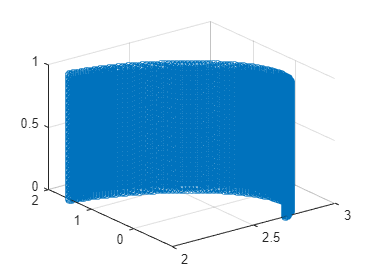

cc = [cc;zeros(length(uu),1)'];

g = zeros(length(tt),3);
for i=1:length(vv)
    t = vv(i);
    vx = -1 - 3*t;
    vy = 3+2*t;
    vz= 4*t;
    g(i,:) = [vx;vy;vz];
end
% g = g';
g = roty(90)*rotx(90)*cc;

% RR = g-g(1,:)+cc;
RR = [];
for i=1:1:length(vv)
        RR = [RR cc + vv(i)*[0;0;1]];
end
figure;
scatter3(RR(1,:),RR(2,:),RR(3,:));

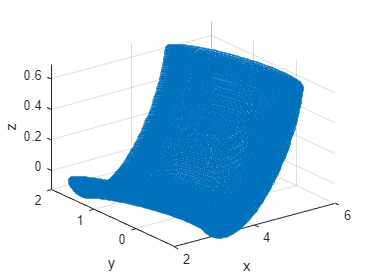



RR2 = [];
for i=1:length(vv)
    for j =1:length(uu)
        RR2 = [RR2 cc(:,i) + g(:,j)- g(:,1)];
    end
end
figure;
scatter3(RR2(1,:),RR2(2,:),RR2(3,:));
% title('ysin(x) - xcos(y) for x and y in [-2\pi,2\pi]')
xlabel('x');
ylabel('y');
zlabel('z');

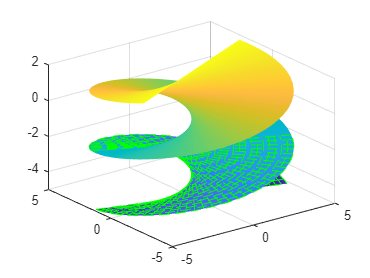



figure;
funx = @(u,v) u.*sin(v);
funy = @(u,v) -u.*cos(v);
funz = @(u,v) v;

fsurf(funx,funy,funz,[-5 5 -5 -2],'--','EdgeColor','g')
hold on
fsurf(funx,funy,funz,[-5 5 -2 2],'EdgeColor','none')
hold off